## 0. Parámetros Físicos

L = 20;              % Distancia de fibra en km (Ej. 25km, 50km)
alpha = 0.2;         % Atenuación de la fibra estándar (dB/km)
Va = 4;              % Varianza de modulación de Alice (VA). Típico: 4-20 SNU.
T = 10^(-alpha * L / 10) %Transmitancia

T = 0.3981

% Parámetros de Ruido
vel = 0.05;          % Ruido electrónico del detector (0.05 = 5% del shot noise)
xi = 0.01;           % Ruido de exceso a la entrada (Excess Noise). Típico: 0.01
% Tamaños
n = 26112

n = 26112

max_iter = 200

max_iter = 200

N_pulsos = 100000 %Número de pulsos que vamos a generar (tiene que ser mayor para generar varias veces)

N_pulsos = 100000

## 1. Generación (Alice)

%Generamos los números Aleatorios de Alice
q_Alice = sqrt(Va)*randn(N_pulsos, 1)

q_Alice =     0.8567
   -0.6133
    4.0810
    2.5154
   -0.9125
   -3.0478
   -1.0740
   -0.0706
   -0.7517
   -6.0304
    0.9165
    1.3915
    3.8782
   -3.8443
   -0.5995


p_Alice = sqrt(Va)*randn(N_pulsos, 1)

p_Alice =     1.0863
    0.8865
    2.0239
   -1.3083
    0.9038
    0.0132
    1.5820
   -0.8228
   -1.0594
   -0.1541
   -0.2441
   -2.7284
   -4.7490
    3.5599
   -0.5661


Xa = zeros(2 * N_pulsos, 1)

Xa =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


% Intercalado (Interleaving)
Xa(1:2:end) = q_Alice; % Posiciones impares: Q
Xa(2:2:end) = p_Alice; % Posiciones pares: P

%Simulación de Ruido
%variables de ruido
var_noise = 1 + vel + T * xi %varianza del ruido

var_noise = 1.0540

std_noise = sqrt(var_noise) %desviación típica del ruido

std_noise = 1.0266

% ruido como tal
z_noise_p = std_noise * randn(N_pulsos, 1)

z_noise_p =    -0.8499
   -0.8265
   -1.0798
    1.2139
    0.1519
    0.8813
   -0.1128
   -0.1632
    1.3030
   -1.4848
   -1.6733
   -0.2395
   -0.3707
   -0.8448
    0.6864


z_noise_q = std_noise * randn(N_pulsos, 1)

z_noise_q =    -0.5278
   -0.4863
   -0.1761
   -1.2183
    2.3932
    0.5222
    0.7498
    0.0285
   -2.5042
    0.1202
    1.1830
   -0.5355
    0.4657
   -0.0018
   -0.2872


## 2. Recepción (Bob)

p_Bob = sqrt(T) * p_Alice + z_noise_p

p_Bob =    -0.1645
   -0.2672
    0.1972
    0.3884
    0.7221
    0.8896
    0.8854
   -0.6823
    0.6345
   -1.5820
   -1.8273
   -1.9610
   -3.3671
    1.4013
    0.3292


q_Bob = sqrt(T) * q_Alice + z_noise_q

q_Bob =     0.0128
   -0.8733
    2.3989
    0.3688
    1.8174
   -1.4009
    0.0721
   -0.0160
   -2.9785
   -3.6847
    1.7613
    0.3425
    2.9128
   -2.4274
   -0.6654


Yb = zeros(2*N_pulsos,1)

Yb =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Yb(1:2:end) = q_Bob; % Posiciones impares: Q
Yb(2:2:end) = p_Bob; % Posiciones pares: P

## 2.1 Representación de Valores y cálculo parámetros interesantes

%Todo esto es muy extra de chati
% Potencia de señal recibida / Potencia de ruido total
Signal_Power_Rx = T * Va;
Noise_Power_Rx  = var_noise;

SNR_lineal = Signal_Power_Rx / Noise_Power_Rx;
SNR_dB = 10 * log10(SNR_lineal)

SNR_dB = 1.7923

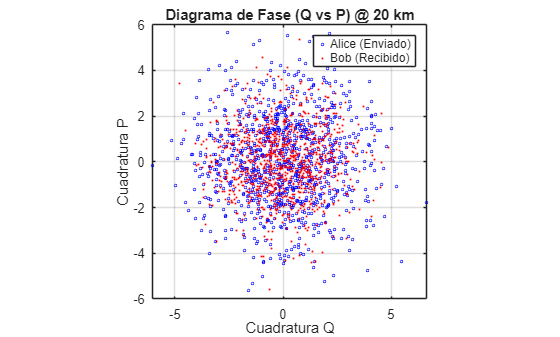


figure;
% Mostramos solo los primeros 1000 puntos para no saturar la gráfica
plot(q_Alice(1:1000), p_Alice(1:1000), 'bo', 'MarkerSize', 2); hold on;
plot(q_Bob(1:1000), p_Bob(1:1000), 'r.', 'MarkerSize', 4);
legend('Alice (Enviado)', 'Bob (Recibido)');
title(['Diagrama de Fase (Q vs P) @ ' num2str(L) ' km']);
xlabel('Cuadratura Q'); ylabel('Cuadratura P');
axis square; grid on;

## 3. Generación de H

% Usamos BG1 con Z=384 (El estándar para alto rendimiento)
Z = 384;            % Factor de Lifting (Tamaño de sub-bloque)
mb = 46;            % Filas del Grafo Base (Para Tasa 1/2)
nb = 68;            % Columnas del Grafo Base

% Dimensiones finales
M = mb * Z         % 17,664 filas (Ecuaciones de paridad)

M = 17664

N = nb * Z         % 26,112 columnas (Bits totales)

N = 26112


% Creamos una matriz que indica el desplazamiento (shift) de cada bloque.
% Usamos una densidad baja (~3-4 conexiones por columna) para que sea "Sparse".

BaseGraph = -1 * ones(mb, nb); % Inicializar todo como "sin conexión"
conexiones_por_columna = 3;

for j = 1:nb
    % Seleccionamos mb filas aleatorias para conectar en esta columna
    filas_activas = randperm(mb, conexiones_por_columna);
    for i = filas_activas
        BaseGraph(i, j) = randi([0, Z-1]); % Valor de rotación aleatorio
    end
end

%% 3. Expansión de la Matriz (Lifting)
% -------------------------------------------------------------------------
% Este bloque simula la lógica que implementará tu FPGA
H = sparse(M, N)

H = 17664×26112 sparse double matrix
   All zero



for i = 1:mb
    for j = 1:nb
        shift_val = BaseGraph(i, j);
        
        if shift_val ~= -1
            % Crear identidad rotada (Barrel Shifter en hardware)
            sub_block = circshift(eye(Z), [0, shift_val]);
            
            % Insertar en la matriz global
            row_idx = (i-1)*Z + 1 : i*Z;
            col_idx = (j-1)*Z + 1 : j*Z;
            H(row_idx, col_idx) = sub_block;
        end
    end
end
H

H = 17664×26112 sparse double matrix (78336 nonzeros)
      (6240,1)              1
     (15543,1)              1
     (16383,1)              1
      (6241,2)              1
     (15544,2)              1
     (16384,2)              1
      (6242,3)              1
     (15545,3)              1
     (16385,3)              1
      (6243,4)              1
     (15546,4)              1
     (16386,4)              1
      (6244,5)              1
     (15547,5)              1
     (16387,5)              1
      (6245,6)              1
     (15548,6)              1
     (16388,6)              1
      (6246,7)              1
     (15549,7)              1
     (16389,7)              1
      (6247,8)              1
     (15550,8)              1
     (16390,8)              1
      (6248,9)              1
     (15551,9)              1
     (16391,9)              1
      (6249,10)             1
     (15552,10)             1
     (16392,10)             1
      (6250,11)             1
     (15553,11) 

## 4. Estimación de parámetros

%Generamos los distintos vectores que necesitamos
Xr = Xa(1:2:2*n) %Los valores de X que vamos a usar para la reconciliación

Xr =     0.1395
    1.5055
   -3.4720
   -4.4328
   -0.5875
   -1.6576
   -4.1963
   -2.5279
    4.2557
   -2.2546
   -0.2823
    0.8973
   -4.3444
   -0.7836
   -0.8613


Xp = Xa(2:2:2*n) %Los valores de X que vamos a usar para la estimación de parámetros

Xp =    -1.4005
   -0.7187
   -1.2357
   -1.7167
    0.6755
    3.4991
   -0.5746
    0.8234
    3.5315
   -1.9929
   -3.3027
   -0.1369
    0.1099
    0.8963
   -2.8830


Yr = Yb(1:2:2*n) %Los valores de Y que vamos a usar para la reconciliación

Yr =    -1.6578
    0.1867
   -0.5150
   -5.7002
   -1.0830
    0.2374
   -2.7067
   -2.7680
    3.0416
   -0.7787
   -0.9282
    0.4066
   -4.2867
   -0.0221
   -1.0618


Yp = Yb(2:2:2*n) %Los valores de Y que vamos a usar para la estimación de parámetros

Yp =    -0.9876
    0.4637
    0.4216
   -0.1670
    0.6397
    1.1523
   -0.3520
   -0.5171
    1.4221
   -1.8796
   -0.8982
    1.4652
    0.7255
    0.9394
   -1.9951


%Estimamos T
Cov_xy = cov(Xp, Yp) %matriz de covarianzas

Cov_xy =     4.0422    2.5415
    2.5415    2.6560


covarianza_xy = Cov_xy(1, 2) 

covarianza_xy = 2.5415

varianza_x = var(Xp)

varianza_x = 4.0422

T_estimada = (covarianza_xy / varianza_x)^2

T_estimada = 0.3953


%Estimación del ruido residual
sigma2 = var(Yp - sqrt(T_estimada)*Xp)

sigma2 = 1.0580

z_est = (sigma2 - 1 - vel)/T_estimada

z_est = 0.0203

## 5. Cálculo del Síndrome

%Calculamos el síndrome
Kb = zeros(n, 1)

Kb =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Kb(Yr <= 0) = 1; 
Kb(Yr > 0)  = 0;
S = mod(H * Kb, 2)

S =      1
     1
     1
     1
     0
     0
     1
     1
     1
     0
     1
     0
     0
     1
     0


## 6. Reconciliación Inversa

%% 6. Reconciliación Inversa — Bucle Min-Sum (Scaled)
% Implementa el algoritmo Belief Propagation (Min-Sum escalado)
% para reconciliación inversa en GG02 CV-QKD.

%% 6.1. Inicialización
% --- LLR iniciales desde los valores de Alice (canal AWGN gaussiano) ---
sigma_noise = sqrt(1 + vel + T_estimada * z_est);
mu = (sqrt(T_estimada) / sigma_noise) * Xr;
LLR = log(normcdf(mu) ./ normcdf(-mu));
LLR = max(min(LLR, 20), -20);

% --- Pre-calcular estructura de aristas de H (no cambia en el bucle) ---
[rows_H, cols_H] = find(H);
num_edges       = length(rows_H);
M_rows          = size(H, 1);   % Número de Check Nodes
N_cols          = size(H, 2);   % Número de Variable Nodes (= n)

% --- Factor de escala Min-Sum ---
alpha_ms = 0.75;

% --- Inicializar mensajes R (Check→Variable) a cero ---
R_edges = zeros(num_edges, 1);

% --- Variables de resultado ---
converged   = false;
Kb_hat      = zeros(n, 1);

%% 6.2. Bucle de Propagación de Creencias
for iter = 1:max_iter

    %% --- Paso 1: Actualización de Variable Node (Variable→Check) ---
    % L(j) = LLR(j) + suma de todos los mensajes R entrantes
    sum_R = accumarray(cols_H, R_edges, [N_cols, 1]);
    L     = LLR + sum_R;

    % Mensaje extrínseco q(arista) = L(col) − R_propio
    % (excluimos el mensaje que viene del mismo Check Node)
    Q_edges = L(cols_H) - R_edges;

    %% --- Paso 2: Actualización de Check Node (Min-Sum escalado) ---
    % 2a. Magnitudes y signos de los mensajes entrantes
    val_abs  = abs(Q_edges);
    signs_q  = sign(Q_edges);
    signs_q(signs_q == 0) = 1;   % Evitar signos nulos

    % 2b. Buscar min1 y min2 para cada Check Node (fila)
    %     Ordenamos aristas por (fila, |valor|)
    [~, sort_idx]      = sortrows([rows_H, val_abs], [1, 2]);
    rows_sorted        = rows_H(sort_idx);
    cols_sorted_tmp    = cols_H(sort_idx);
    val_abs_sorted     = val_abs(sort_idx);

    [unique_rows, first_idx] = unique(rows_sorted, 'first');

    min1_vals_vec = zeros(M_rows, 1);
    min1_cols_vec = zeros(M_rows, 1);
    min2_vals_vec = zeros(M_rows, 1);

    min1_vals_vec(unique_rows) = val_abs_sorted(first_idx);
    min1_cols_vec(unique_rows) = cols_sorted_tmp(first_idx);
    safe_next = min(first_idx + 1, length(rows_sorted));
valid_mask = (first_idx + 1) <= length(val_abs_sorted) & rows_sorted(safe_next) == unique_rows;
    min2_vals_vec(unique_rows(valid_mask)) = val_abs_sorted(first_idx(valid_mask) + 1);


    % 2c. Expandir mínimos al tamaño del vector de aristas
    vals_min1_exp = min1_vals_vec(rows_H);
    vals_min2_exp = min2_vals_vec(rows_H);
    cols_min1_exp = min1_cols_vec(rows_H);   % <-- BUG CORREGIDO: antes no estaba definido

    % 2d. Si esta arista ES la que tiene min1, usar min2 (mensaje extrínseco)
    is_min_col = (cols_H == cols_min1_exp);
    R_mags                   = zeros(num_edges, 1);
    R_mags(~is_min_col)      = vals_min1_exp(~is_min_col);
    R_mags(is_min_col)       = vals_min2_exp(is_min_col);
    R_mags                   = alpha_ms * R_mags;   % Escalado

    % 2e. Calcular signo del mensaje R
    %     Producto de signos de la fila, ajustado por el síndrome S
    is_neg_sparse        = sparse(rows_H, cols_H, double(signs_q < 0), M_rows, N_cols);
    num_neg_per_row      = full(sum(is_neg_sparse, 2));
    row_parity_signs     = (-1) .^ num_neg_per_row;
    syndrome_adjustment  = (-1) .^ S;
    global_row_signs     = row_parity_signs .* syndrome_adjustment;

    signs_expanded = global_row_signs(rows_H);
    final_signs    = signs_expanded .* signs_q;

    % 2f. Mensaje R final para esta iteración
    R_edges = final_signs .* R_mags;

    %% --- Paso 3: Decisión y Comprobación de Convergencia ---
    sum_R_final = accumarray(cols_H, R_edges, [N_cols, 1]);
    L_total     = LLR + sum_R_final;

    Kb_hat          = zeros(n, 1);
    Kb_hat(L_total < 0) = 1;   % Bit = 1 si LLR total < 0

    S_check = mod(H * Kb_hat, 2);

    if all(S_check == S)
        converged = true;
        fprintf('✔ Convergencia en iteración %d/%d\n', iter, max_iter);
        break;
    end
end

if ~converged
    fprintf('✘ No convergió en %d iteraciones\n', max_iter);
end

✘ No convergió en 200 iteraciones



%% 6.3. Resultados
BER_reconciliacion = sum(Kb_hat ~= Kb) / n;
fprintf('BER tras reconciliación: %.4e\n', BER_reconciliacion);

BER tras reconciliación: 1.5832e-01
